# Initialization (Refer to "Reference_original.jpg")

close all;
clear all;
clc;

length_pole = 9;                % length of AC
length_BF = 9.5;                %% 
length_DG = 2;                  %% Used only for initial calculations when canopy is open
length_BD = sqrt(length_DG^2+(length_BF/2)^2);
length_BE = length_BD/2;
length_CE = length_BE;

closed_DG = 5;
open_DG = 1.5;
max_slider_height = 7;
min_slider_height = 4;

increments = 50;
DG_lengths = linspace(closed_DG, open_DG, increments);     
slider_heights = linspace(min_slider_height, max_slider_height, increments);    % represents point B


## Phase 1: Raising the slider

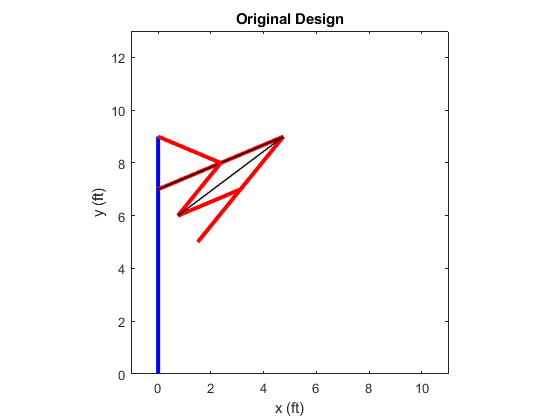

figure(1);

for i= 1:increments
    hold off;
    
    %% Position Calculations
    Ax(i) = 0;
    Ay(i) = 0;
    Cx(i) = 0;
    Cy(i) = length_pole;
    Bx(i) = 0;
    By(i) = slider_heights(i);
    
    a = length_pole - By(i);
    b = length_BE;
    c = length_CE;
    

    theta = acos((a^2+b^2-c^2)/(2*a*b));    % Cosine Law
    
    Ex(i) = length_BE*sin(theta);
    Ey(i) = By(i) + length_BE* cos(theta);
    Dx(i) = length_BD*sin(theta);
    Dy(i) = By(i) + length_BD* cos(theta);
    

    length_DH = 0.5*closed_DG;
    length_ED = length_BD - length_BE;
    length_EH = sqrt(length_ED^2 - length_DH^2);
    
    beta = asin(length_DH/length_ED);
    
    Hx(i) = Ex(i) + length_EH *cos((pi/2 - theta)-beta);
    Hy(i) = Ey(i) + length_EH *sin((pi/2 - theta)-beta);
    Ix(i) = Ex(i) + 2*length_EH *cos((pi/2 - theta)-beta);
    Iy(i) = Ey(i) + 2*length_EH *sin((pi/2 - theta)-beta);
    Gx(i) = 2*Hx(i) - Dx(i);
    Gy(i) = 2*Hy(i) - Dy(i);
    Fx(i) = 2*Gx(i) - Bx(i);
    Fy(i) = 2*Gy(i) - By(i);
    
    
    %% Plots
    plot( [Ax(i) Cx(i)], [Ay(i), Cy(i)],'Color','b','LineWidth',3);
    hold on;
    plot( [Bx(i) Dx(i)], [By(i), Dy(i)],'Color','r','LineWidth',3);
    plot( [Bx(i) Dx(i)], [By(i), Dy(i)],'Color','black','LineWidth',1); 
    plot( [Cx(i) Ex(i)], [Cy(i), Ey(i)],'Color','r','LineWidth',3);
    plot( [Ex(i) Gx(i)], [Ey(i), Gy(i)],'Color','r','LineWidth',3);
    plot( [Gx(i) Ix(i)], [Gy(i), Iy(i)],'Color','r','LineWidth',3);
    plot( [Dx(i) Fx(i)], [Dy(i), Fy(i)],'Color','r','LineWidth',3);
    plot( [Dx(i) Gx(i)], [Dy(i), Gy(i)],'Color','black','LineWidth',1);
    
    xlabel("x (ft)");
    ylabel("y (ft)");
    xlim([-1 11]);
    ylim([0 13]);
    title("Original Design");
    daspect([1 1 1]);
    
    pause(0.02);
end

pause(2);

## Phase 2: Pulling the string to open canopy

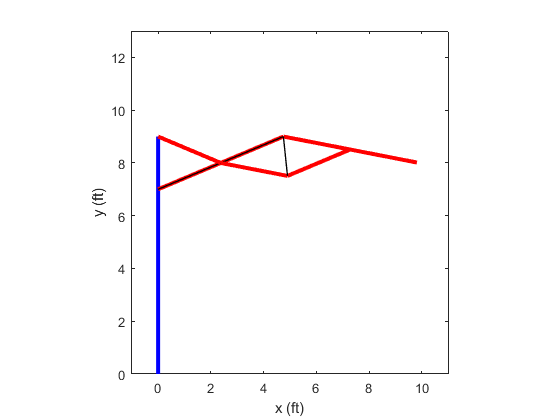

for i= increments+1:2*increments
    hold off;
    
    %% Static points calculation: A, B, C, D, E
    Ax(i) = 0;
    Ay(i) = 0;
    Cx(i) = 0;
    Cy(i) = length_pole;
    Bx(i) = 0;
    By(i) = max_slider_height;
    
    a = length_pole - By(i);
    b = length_BE;
    c = length_CE;
    
    theta = acos((a^2+b^2-c^2)/(2*a*b));
    
    Ex(i) = length_BE*sin(theta);
    Ey(i) = By(i) + length_BE* cos(theta);
    Dx(i) = length_BD*sin(theta);
    Dy(i) = By(i) + length_BD*cos(theta);
    
    
    %% Dynamic points calculation:
    length_DH = 0.5*DG_lengths(i - increments);
    length_ED = length_BD - length_BE;
    length_EH = sqrt(length_ED^2 - length_DH^2);
    
    beta = asin(length_DH/length_ED);
    
    Hx(i) = Ex(i) + length_EH *cos((pi/2 - theta)-beta);
    Hy(i) = Ey(i) + length_EH *sin((pi/2 - theta)-beta);
    Ix(i) = Ex(i) + 2*length_EH *cos((pi/2 - theta)-beta);
    Iy(i) = Ey(i) + 2*length_EH *sin((pi/2 - theta)-beta);
    Gx(i) = 2*Hx(i) - Dx(i);
    Gy(i) = 2*Hy(i) - Dy(i);
    Fx(i) = 2*Gx(i) - Bx(i);
    Fy(i) = 2*Gy(i) - By(i);
    
    %% Plots
    plot( [Ax(i) Cx(i)], [Ay(i), Cy(i)],'Color','b','LineWidth',3);
    hold on;
    plot( [Bx(i) Dx(i)], [By(i), Dy(i)],'Color','r','LineWidth',3); 
    plot( [Bx(i) Dx(i)], [By(i), Dy(i)],'Color','black','LineWidth',1); 
    plot( [Cx(i) Ex(i)], [Cy(i), Ey(i)],'Color','r','LineWidth',3);
    plot( [Ex(i) Gx(i)], [Ey(i), Gy(i)],'Color','r','LineWidth',3);
    plot( [Gx(i) Ix(i)], [Gy(i), Iy(i)],'Color','r','LineWidth',3);
    plot( [Dx(i) Fx(i)], [Dy(i), Fy(i)],'Color','r','LineWidth',3);
    plot( [Dx(i) Gx(i)], [Dy(i), Gy(i)],'Color','black','LineWidth',1);

    xlabel("x (ft)");
    ylabel("y (ft)");
    xlim([-1 11]);
    ylim([0 13]);
    daspect([1 1 1]);
    
    pause(0.02);
end

## Velocity of Tip

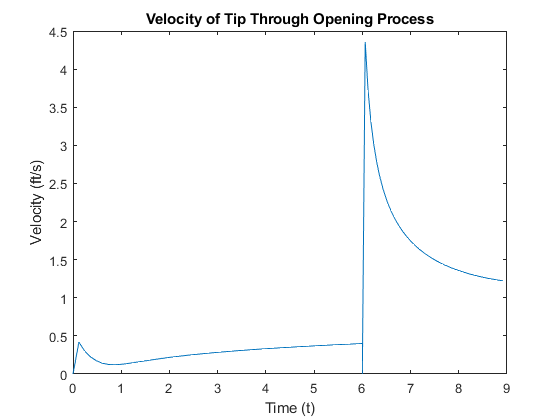

% Phase 1
max_t1 = 6;
time = linspace(0, 6, increments);


% Phase 2
theta2_dot = 3*pi;            % r/s
r = 1 /2/12;                  % radius of pinion (ft)

v = r*theta2_dot;                        % linear velocity of rack [ft/s]                    
max_t2 = (closed_DG-open_DG)/v;
time = [time linspace(max_t1, max_t2, increments)];

increment_t = max_t1/(increments - 1);       % time per increment


% Velocity of Tip
figure(2);

speed_Fx = diff(Fx)/increment_t;
speed_Fy = diff(Fy)/increment_t;
velocity_F = sqrt(speed_Fx.^2 + speed_Fy.^2);

plot(time, [0 velocity_F]);
xlabel("Time (t)");
ylabel("Velocity (ft/s)");
title("Velocity of Tip Through Opening Process");

## Phase 3: Tilt adjustment

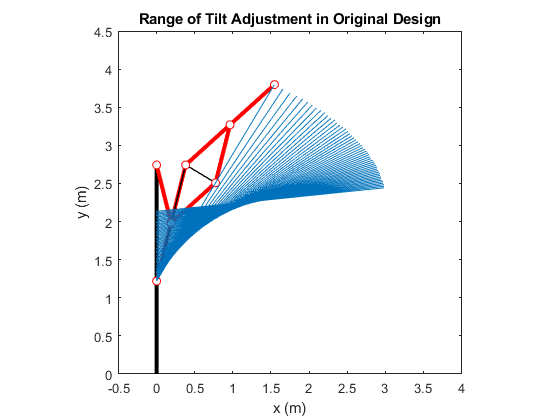

figure(4);

for i= 1:increments
    hold off;
    
    %% Position Calculations
    Ax(i) = 0;
    Ay(i) = 0;
    Cx(i) = 0;
    Cy(i) = length_pole;
    Bx(i) = 0;
    By(i) = slider_heights(increments -i +1);
    
    a = length_pole - By(i);
    b = length_BE;
    c = length_CE;
    
    theta = acos((a^2+b^2-c^2)/(2*a*b));
    
    Ex(i) = length_BE*sin(theta);
    Ey(i) = By(i) + length_BE* cos(theta);
    Dx(i) = length_BD*sin(theta);
    Dy(i) = By(i) + length_BD* cos(theta);
    

    length_DH = 0.5*open_DG;                % Maintain canopy open state
    length_ED = length_BD - length_BE;
    length_EH = sqrt(length_ED^2 - length_DH^2);
    
    beta = asin(length_DH/length_ED);
    
    Hx(i) = Ex(i) + length_EH *cos((pi/2 - theta)-beta);
    Hy(i) = Ey(i) + length_EH *sin((pi/2 - theta)-beta);
    Ix(i) = Ex(i) + 2*length_EH *cos((pi/2 - theta)-beta);
    Iy(i) = Ey(i) + 2*length_EH *sin((pi/2 - theta)-beta);
    Gx(i) = 2*Hx(i) - Dx(i);
    Gy(i) = 2*Hy(i) - Dy(i);
    Fx(i) = 2*Gx(i) - Bx(i);
    Fy(i) = 2*Gy(i) - By(i);
    
    
    %% Convert from ft to m
    Ax(i) = Ax(i) * 0.3048;
    Ay(i) = Ay(i) * 0.3048;
    Bx(i) = Bx(i) * 0.3048;
    By(i) = By(i) * 0.3048;
    Cx(i) = Cx(i) * 0.3048;
    Cy(i) = Cy(i) * 0.3048;
    Dx(i) = Dx(i) * 0.3048;
    Dy(i) = Dy(i) * 0.3048;
    Ex(i) = Ex(i) * 0.3048;
    Ey(i) = Ey(i) * 0.3048;
    Fx(i) = Fx(i) * 0.3048;
    Fy(i) = Fy(i) * 0.3048;
    Gx(i) = Gx(i) * 0.3048;
    Gy(i) = Gy(i) * 0.3048;
    Hx(i) = Hx(i) * 0.3048;
    Hy(i) = Hy(i) * 0.3048;
    Ix(i) = Ix(i) * 0.3048;
    Iy(i) = Iy(i) * 0.3048;
    
    %% Plots
    plot( [Ax(i) Cx(i)], [Ay(i), Cy(i)],'Color','black','LineWidth',3);
    hold on;
    plot( [Bx(i) Dx(i)], [By(i), Dy(i)],'Color','r','LineWidth',3);
    plot( [Bx(i) Dx(i)], [By(i), Dy(i)],'Color','black','LineWidth',1); 
    plot( [Cx(i) Ex(i)], [Cy(i), Ey(i)],'Color','r','LineWidth',3);
    plot( [Ex(i) Gx(i)], [Ey(i), Gy(i)],'Color','r','LineWidth',3);
    plot( [Gx(i) Ix(i)], [Gy(i), Iy(i)],'Color','r','LineWidth',3);
    plot( [Dx(i) Fx(i)], [Dy(i), Fy(i)],'Color','r','LineWidth',3);
    plot( [Dx(i) Gx(i)], [Dy(i), Gy(i)],'Color','black','LineWidth',1);
    plot(Bx(i), By(i), 'ro','MarkerFaceColor','w');
    plot(Cx(i), Cy(i), 'ro','MarkerFaceColor','w');
    plot(Dx(i), Dy(i), 'ro','MarkerFaceColor','w');
    plot(Ex(i), Ey(i), 'ro','MarkerFaceColor','w');
    plot(Fx(i), Fy(i), 'ro','MarkerFaceColor','w');
    plot(Gx(i), Gy(i), 'ro','MarkerFaceColor','w');
    plot(Ix(i), Iy(i), 'ro','MarkerFaceColor','w');
    
    for j= 1:i
        line([Bx(j) Fx(j)],[By(j) Fy(j)]);      %% Draws the angle trajectories
    end
    
    title("Range of Tilt Adjustment in Original Design");
    xlabel("x (m)");
    ylabel("y (m)");
    xlim([-0.5 4]);
    ylim([0 4.5]);
    daspect([1 1 1]);
    
    pause(0);
end


max_canopy_angle = atan((Fy(i) - By(i))/Fx(i) - Bx(i)) *180/pi

max_canopy_angle = 59.0434

min_canopy_angle = atan((Fy(1) - By(1))/Fx(1) - Bx(1)) *180/pi

min_canopy_angle = 5.9133


alpha = theta*180/pi

alpha = 14.0362